## Problem Statement

Given some transfer matrix $H(s)=L(s)R^{-1}(s)$, where $L(s)$ and $R(s)$ have realizations structured according to adjacency matrix $\mathcal{A}$, we hope to generate a realization of $H(s)$ that is structured according to $\mathcal{A}$.

## Background on Graphs

A graph is a mathematical object used to represent the interconnection of subsystems. A graph is a set of nodes (or vertices), denoted $\mathcal{V}$, and a set of edges, denoted $\mathcal{E}$. The nodes are the subsystems, and the edges are used to represent whether one subsystem is connected to another.

The most common notation is to denote the set of nodes as $\mathcal{V} = \{1,2,\dots,N\}$, essentially just integer labels for each subsystem. Typically the set of edges is denoted $\mathcal{E} = \{(i_1,j_1), (i_2,j_2),\dots\}$. If an ordered pair $(i,j)$ is an element in $\mathcal{E}$, then the graph has an edge from the node labeled by $i$ to the node labeled $j$.

A useful way to represent a graph is by its adjacency matrix, $\mathcal{A}$. The adjacency matrix is an $N\times N$ matrix whose elements are binary. The element of $\mathcal{A}$ in row $i$ and column $j$ is 1 if the graph has an edge from $i$ to $j$ and 0 if the graph does not have an edge from $i$ to $j$. Formally


$$\mathcal{A}_{ij} = \begin{cases}1 & (i,j)\in\mathcal{E}\\ 0 & (i,j)\not\in\mathcal{E}\end{cases}$$


Here's an example to clarify:

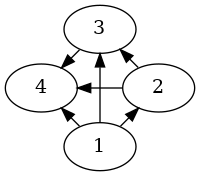

The vertex set is $\mathcal{V}=\{1,2,3,4\}$ and the edge set is $\mathcal{E} = \{(1,2),(1,3),(1,4),(2,3),(2,4),(3,4)\}$. The adjacency matrix will then be


$$\mathcal{A} = \left[\begin{array}{cccc}0&1&1&1\\0&0&1&1\\0&0&0&1\\0&0&0&0\end{array}\right]$$


In distributed control, we use graphs to represent the causality between subsystems. Each node is a subsystem with some internal state. An edge exists from $i$ to $j$ if the state of subsystem $j$ depends on the state of subsystem $i$. This is essentially a way of prescribing which subsystems are allowed to communicate with each other.

## Background on Index Sets

In order to accomplish the task of finding a realization that can be implemented on a distributed network, any piece of code will have to keep track of and perform manipulations based on index sets.

Formal descriptions of index sets are given in [Lessard et al 2019](https://arxiv.org/pdf/1212.1839) Definitions 1 and 2 [Vamsi and Elia 2015](https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=7109152) Section IIB. Index sets are used to describe the way a matrix is block partitioned, specifically telling us the size of each partitioned block.

For example, let the matrix $A$ be partitioned according to the index set $(n_1,n_2, \dots, n_N), (m_1,m_2,\dots,m_M)$. The tuple $(n_1,n_2,\dots,n_N)$ tells us that the matrix $A$ has $N$ block rows, with the number of actuals rows of the first block row being $n_1$, the second block row having $n_2$ rows, etc. The tuple $(m_1,m_2,\dots,m_M)$ tells us that $A$ has $M$ block columns with the first block columns having $m_1$ actual columns and so on.

This means that the matrix $A$ can be written in a block partitioned form as 


$$A=\left[\begin{array}{cccc}A_{11}&A_{12}&\cdots&A_{1M}\\A_{21}&A_{22}&\cdots&A_{2M}\\\vdots&\vdots&\ddots&\vdots\\A_{N1}&A_{N2}&\cdots&A_{NM}\end{array}\right]$$


and that the block $A_{ij}$ has size $n_i \times m_i$.

Index sets are important because we want to ensure that certain matrices have certain block sparsity structures *given an index set*. To show why this last part is important consider the following example.


$$A=\left[\begin{array}{cccccc}1&1&0&0&0&0\\1&1&0&0&0&0\\0&0&1&1&0&0\\0&0&1&1&0&0\\0&0&0&0&1&1\\0&0&0&0&1&1\end{array}\right]$$


If we partition $A$ according to the index set $(2,2,2),(2,2,2)$,


$$A=\left[\begin{array}{cc|cc|cc}1&1&0&0&0&0\\1&1&0&0&0&0\\\hline0&0&1&1&0&0\\0&0&1&1&0&0\\\hline0&0&0&0&1&1\\0&0&0&0&1&1\end{array}\right]$$


then clearly only the diagonal blocks are nonzero, so $A$ has the sparsity structure


$$\mathrm{sp}(A) = \left[\begin{array}{ccc}1&0&0\\0&1&0\\0&0&1\end{array}\right]$$


Alternatively, if we partition $A$ according to the index set $(1,2,3),(1,2,3)$, 


$$A=\left[\begin{array}{c|cc|ccc}1&1&0&0&0&0\\\hline1&1&0&0&0&0\\0&0&1&1&0&0\\\hline0&0&1&1&0&0\\0&0&0&0&1&1\\0&0&0&0&1&1\end{array}\right]$$


then all but two blocks are nonzero and $A$ has the sparsity structure


$$\mathrm{sp}(A) = \left[\begin{array}{ccc}1&1&0\\1&1&1\\0&1&1\end{array}\right]$$


Since the block sparsity structure of a matrix depends on the index set used to partition the matrix, the index sets are something we need to track of when trying to achieve a desired block sparsity structure.

## Connection Between Graph Structure and Index Sets in Distributed Control

On a distributed network, each subcontroller (node) will have a prespecified number of inputs, outputs, and internal states. The number of inputs, outputs and states tells us the sizes of the partitioned blocks of relevant matrices, and therefore tells us what the sparsity structure (with respect to a certain index set) the controller will have.

In order to implement a controller on a distributed network, the controller must have a certain block sparsity structure. The index sets tell us how to partition the the relevant matrices in order to determine block sparsity structure, and the graph's adjacency matrix tells us what that sparsity structure should be.

## Generating an Arbitrary Realization to Transform

This entire section is not critical to understand. All we're doing here is generating some matrices of the form we would expect as an input to the problem we actually care about. We do this so that in the next section we have matrices we can apply our transformation procedure on.

First we will create arbitrary structured (upper triangular) realizations of $L(s)$ and $R(s)$ that we will just use to test on.

clear; clc;

adjacency = [1,1,1;
            0,1,1;
            0,0,1]; %structure
idx_set_L = randi(4,[3,1]); %number of states in each block of L
idx_set_R = randi(4,[3,1]); %number of states in each block of R

%create some random realizations of R and L that have the proper structure
%and index sets
tot_state_L = sum(idx_set_L); tot_state_R = sum(idx_set_R);

A_L = zeros(tot_state_L); A_R = zeros(tot_state_R);
B_L = zeros(tot_state_L,3); B_R = zeros(tot_state_R,3);
C_L = zeros(3,tot_state_L); C_R = zeros(3,tot_state_R);
D_L = zeros(3); D_R = zeros(3);

idx_inc_L = [0;cumsum(idx_set_L)]; idx_inc_R = [0;cumsum(idx_set_R)]; %just makes keeping track of where to
                                                                    %place the blocks easier

for i = 1:3 %rows
    for j = 1:3 %columns
        if adjacency(i,j)
            rows_L = idx_inc_L(i)+1:idx_inc_L(i+1); rows_R = idx_inc_R(i)+1:idx_inc_R(i+1);
            cols_L = idx_inc_L(j)+1:idx_inc_L(j+1); cols_R = idx_inc_R(j)+1:idx_inc_R(j+1);

            A_block_L = rand(idx_set_L(i),idx_set_L(j)); A_block_R = rand(idx_set_R(i),idx_set_R(j));
            A_L(rows_L,cols_L) = A_block_L; A_R(rows_R,cols_R) = A_block_R;

            C_block_L = rand(1,idx_set_L(j)); C_block_R = rand(1,idx_set_R(j));
            C_L(i,cols_L) = C_block_L; C_R(i,cols_R) = C_block_R;
            if i == j
                B_block_L = rand(idx_set_L(i),1); B_block_R = rand(idx_set_R(i),1);
                B_L(rows_L,i) = B_block_L; B_R(rows_R,i) = B_block_R;
            end
        end
    end
end

We have found that for realizations


$$L(s)=\left[\begin{array}{c|c} A_L & B_L \\ \hline C_L & 0 \end{array}\right],~~ R(s)=\left[\begin{array}{c|c} A_R & B_R \\ \hline C_R & 0 \end{array}\right]$$


one realization of $L(s)R^{-1}(s)$ is given by


$$L(s)R^{-1}(s) = \left[\begin{array}{cc|c}A_R-B_RC_R(A_R+pI) & 0 & B_R\\ -B_LC_R(A_R+pI) & A_L & B_L\\ \hline -C_LB_LC_R(A_R+pI) & C_L(A_L+pI)& C_LB_L\end{array}\right] =: \left[\begin{array}{cc|c} A_K^{11} & A_K^{12} & B_K^1\\ A_K^{21} & A_K^{22} & B_K^2\\ \hline C_K^1 & C_K^2 & D_K\end{array}\right]$$


where $p$ is some arbitrary scalar. 

p = 1;

AK11 = A_R - B_R*C_R*(A_R+p*eye(tot_state_R)); AK12 = zeros(tot_state_R,tot_state_L);
AK21 = -B_L*C_R*(A_R+p*eye(tot_state_R)); AK22 = A_L;

BK1 = B_R; BK2 = B_L;
CK1 = -C_L*B_L*C_R*(A_R+p*eye(tot_state_R)); CK2 = C_L*(A_L+p*eye(tot_state_L));
DK = C_L*B_L;

AK = [AK11, AK12;
    AK21, AK22];
BK = [BK1; BK2];
CK = [CK1, CK2];

## Finding a Distributed Implementation

Everything so far has just been setting us up with an example we can try to get a network realization for. Now we actually tackle the problem of creating the network realization.

Let the state of the $i^{th}$ block of $R(s)$ be called $\xi_i$ and the state of the $i^{th}$ block of $L(s)$ be called $\zeta_i$. The realization we have created in the last section has the states stacked as


$$x_K = \left[\begin{array}{c} \xi_1 \\ \xi_2 \\ \xi_3 \\ \zeta_1 \\ \zeta_2 \\ \zeta_3 \end{array}\right]$$


but in order for the realization to be implementable with a distributed architecture, we want the states to be stacked as


$$\tilde{x}_K = \left[\begin{array}{c} \xi_1 \\ \zeta_1 \\ \xi_2 \\ \zeta_2 \\ \xi_3 \\ \zeta_3 \end{array}\right]$$


In order to find a realization where the states are stacked the way we want, we need to find an invertible transformation $T$ such that $Tx_K = \tilde{x}_K$. The transformation is of the form


$$T=\left[\begin{array}{cccccc}I&0&0&0&0&0\\0&0&0&I&0&0\\0&I&0&0&0&0\\0&0&0&0&I&0\\0&0&I&0&0&0\\0&0&0&0&0&I\end{array}\right]$$


though the sizes of each block is at this point somewhat ambiguous. Let the sizes be


$$\xi_1 \in \mathbb{R}^{n_1}\\
\xi_2 \in \mathbb{R}^{n_2}\\
\xi_3 \in \mathbb{R}^{n_3}\\
\zeta_1 \in \mathbb{R}^{m_1}\\
\zeta_2 \in \mathbb{R}^{m_2}\\
\zeta_3 \in \mathbb{R}^{m_3}$$


Then specifically the blocks of $T$ are


$$T=\left[\begin{array}{c} I^{n_1\times n_1}&0^{n_1\times n_2}&0^{n_1\times n_3}&0^{n_1\times m_1}&0^{n_1\times m_2}&0^{n_1\times m_3}\\0^{m_1\times n_1}&0^{m_1\times n_2}&0^{m_1\times n_3}&I^{m_1\times m_1}&0^{m_1\times m_2}&0^{m_1\times m_3}\\0^{n_2\times n_1}&I^{n_2\times n_2}&0^{n_2\times n_3}&0^{n_2\times m_1}&0^{n_2\times m_2}&0^{n_2\times m_3}\\0^{m_2\times n_1}&0^{m_2\times n_2}&0^{m_2\times n_3}&0^{m_2\times m_1}&I^{m_2\times m_2}&0^{m_2\times m_3}\\0^{n_3\times n_1}&0^{n_3\times n_2}&I^{n_3\times n_3}&0^{n_3\times m_1}&0^{n_3\times m_2}&0^{n_3\times m_3}\\0^{m_3\times n_1}&0^{m_3\times n_2}&0^{m_3\times n_3}&0^{m_3\times m_1}&0^{m_3\times m_2}&I^{m_3\times m_3} \end{array}\right]$$


Let construct this transformation.

I_locs = [1,0,0,0,0,0;
          0,0,0,1,0,0;
          0,1,0,0,0,0;
          0,0,0,0,1,0;
          0,0,1,0,0,0;
          0,0,0,0,0,1]; %placement of I blocks

old_idx_set = [idx_set_R;idx_set_L]; %index set of the original K realization
new_idx_set = []; %index set of the K realization after T transformation
for i = 1:length(idx_set_L)
    new_idx_set = [new_idx_set; idx_set_R(i)];
    new_idx_set = [new_idx_set; idx_set_L(i)];
end

block_sizes = zeros(length(new_idx_set),length(new_idx_set),2); %used to store the size of each block of T
%populate block_sizes from old and new index sets
for i = 1:length(new_idx_set) %rows
    for j = 1:length(old_idx_set) %cols
        num_rows = new_idx_set(i); num_cols = old_idx_set(j);
        block_sizes(i,j,:) = reshape([num_rows,num_cols],[1,1,2]); %reshaping necessary to store in a 3D array
    end
end

%loop through and put I and 0 blocks of the proper size in the proper locations
T = [];
for i = 1:length(new_idx_set) %rows
    T_block_row = [];
    for j = 1:length(old_idx_set) %cols
        if I_locs(i,j)
            T_block_row = [T_block_row, eye(reshape(block_sizes(i,j,:),[1,2]))]; %append I block
        else
            T_block_row = [T_block_row, zeros(reshape(block_sizes(i,j,:),[1,2]))]; %append 0 block
        end
    end
    T = [T;T_block_row];
end

For a realization


$$\dot{x} = Ax + Bu \\ y = Cx + Du$$


when we change to the transformed variable $\tilde{x} = Tx$, the realization becomes


$$\dot{\tilde{x}} = \underbrace{TAT^{-1}}_{\tilde{A}} \tilde{x} + \underbrace{TB}_{\tilde{B}} u \\ y = \underbrace{CT^{-1}}_{\tilde{C}}\tilde{x} + Du$$


AK_til = T*AK/T; BK_til = T*BK; CK_til = CK/T;

After this transformation the states are grouped according to nodes. The $i^{th}$ node has $n_i+m_i$ states, 1 input and 1 output.

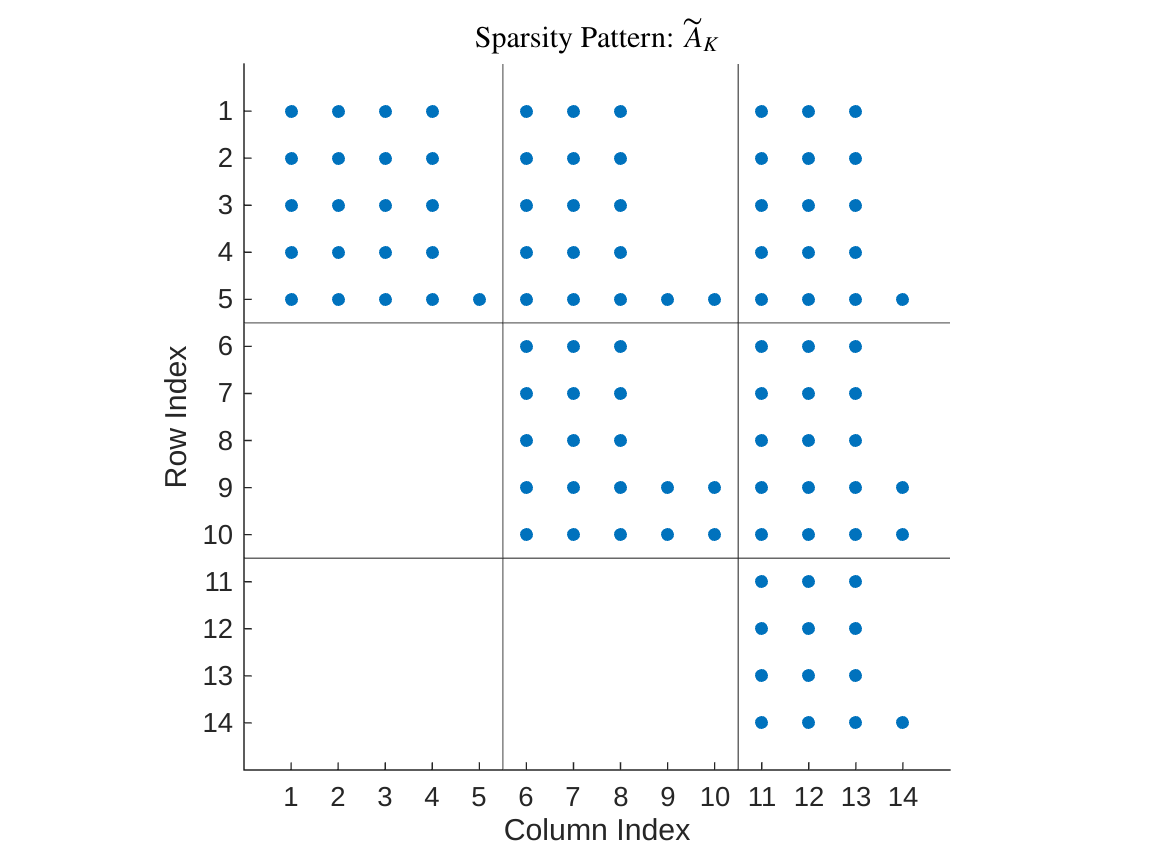

idx_set_by_node = idx_set_L+idx_set_R;
spsty_idx_set(AK_til,idx_set_by_node,idx_set_by_node);
title('Sparsity Pattern: $\tilde{A}_K$','Interpreter','latex')

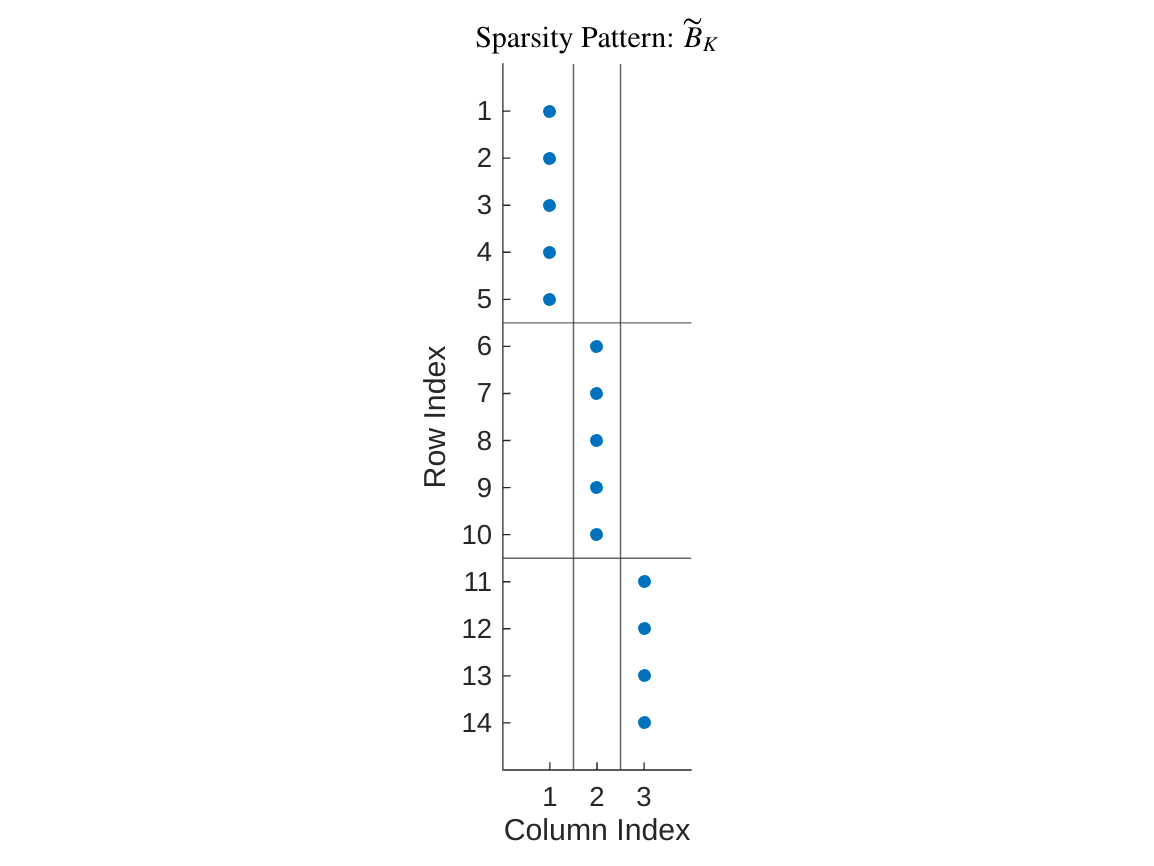

spsty_idx_set(BK_til,idx_set_by_node,ones(3));
title('Sparsity Pattern: $\tilde{B}_K$','Interpreter','latex')

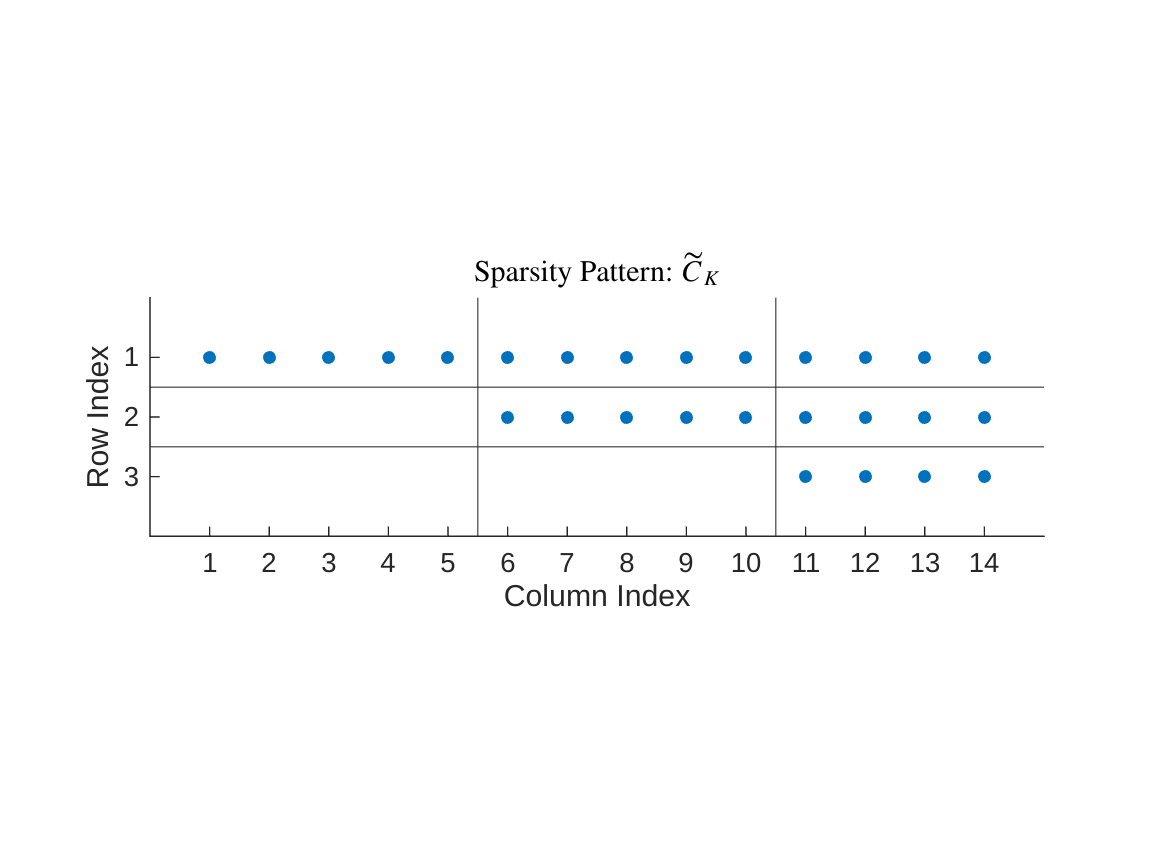

spsty_idx_set(CK_til,ones(3),idx_set_by_node);
title('Sparsity Pattern: $\tilde{C}_K$','Interpreter','latex')

Matrices $\tilde{A}_K$, $\tilde{B}_K$, and $\tilde{C}_K$ now have the required sparsity structure of [Rantzer 2019](https://arxiv.org/pdf/1812.07748) eqn 1.

(Note the $\tilde{D}_K$ matrix does not have the block diagonal structure required by [Rantzer 2019](https://arxiv.org/pdf/1812.07748). This is because transforming the state from $x$ to $\tilde{x}$ has no effect on the feedthrough of the new realization. In order to have $\tilde{D}_K$ in the right form, we need to have found a realization of $L(s)$ such that $C_LB_L$ is block diagonal; this is a separate problem.)

## Next Steps

In order to extend this,

- Need to generalize the procedure for finding $T$ for an arbitrary number of nodes (i.e. by not hard coding in I_locs, line 51)

- The process of constructing $T$ (lines 51-86) is currently designed for clarity, not efficiency. A more efficeint implementation will minimize looping and/or preallocate memory rather than appending at each iteration. In the end, we may want to generate to $T$ with a process similar to lines 18-38.